files = dir("performance_data/*_perform.csv")

files = 12×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


names = string.empty(length(files), 0);
for i = 1:length(files)
     names(i) = files(i).name;
end
names = names'

names = 12×1 string array
    "characteristic_bolete.h5_ed_perform.csv"
    "characteristic_bolete.h5_perform.csv"
    "characteristic_bolete_lowres.h5_ed_perform.csv"
    "characteristic_bolete_lowres.h5_perform.csv"
    "direct_bolete.h5_ed_perform.csv"
    "direct_bolete.h5_perform.csv"
    "direct_bolete_lowres.h5_ed_perform.csv"
    "direct_bolete_lowres.h5_perform.csv"
    "direct_ed_bolete.h5_ed_perform.csv"
    "direct_ed_bolete.h5_perform.csv"
    "direct_ed_bolete_lowres.h5_ed_perform.csv"
    "direct_ed_bolete_lowres.h5_perform.csv"


cfiles = names(contains(names, "characteristic"))

cfiles = 4×1 string array
    "characteristic_bolete.h5_ed_perform.csv"
    "characteristic_bolete.h5_perform.csv"
    "characteristic_bolete_lowres.h5_ed_perform.csv"
    "characteristic_bolete_lowres.h5_perform.csv"


clen = length('characteristic');
dfiles = names(contains(names, "direct"))

dfiles = 8×1 string array
    "direct_bolete.h5_ed_perform.csv"
    "direct_bolete.h5_perform.csv"
    "direct_bolete_lowres.h5_ed_perform.csv"
    "direct_bolete_lowres.h5_perform.csv"
    "direct_ed_bolete.h5_ed_perform.csv"
    "direct_ed_bolete.h5_perform.csv"
    "direct_ed_bolete_lowres.h5_ed_perform.csv"
    "direct_ed_bolete_lowres.h5_perform.csv"


suffix = '_bolete.h5_ed_perform.csv'

aucC = 0.0717

aucD = 0.0491

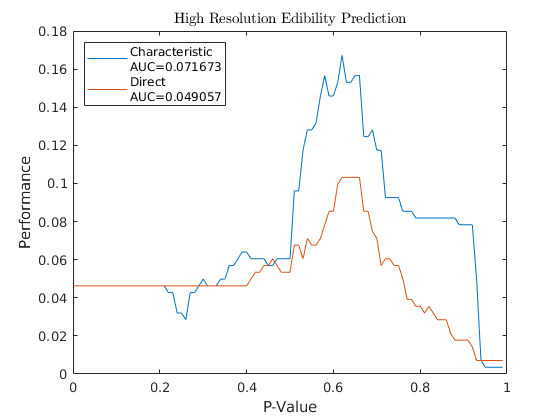

suffix = '_bolete.h5_perform.csv'

aucC = 0.0795

aucD = 0.1004

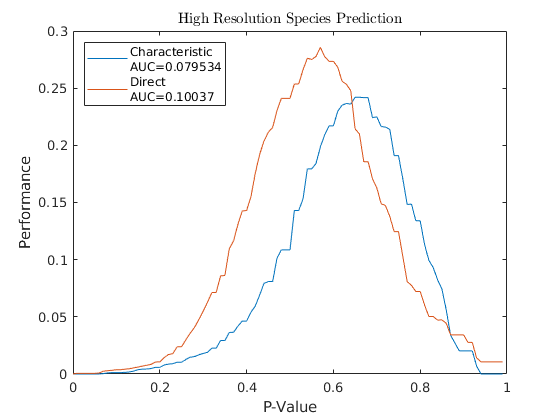

suffix = '_bolete_lowres.h5_ed_perform.csv'

aucC = 0.0723

aucD = 0.0638

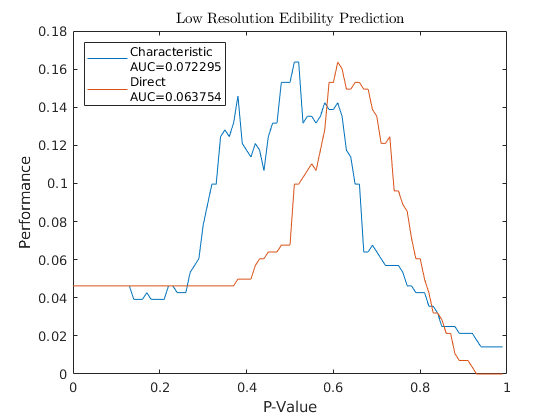

suffix = '_bolete_lowres.h5_perform.csv'

aucC = 0.0875

aucD = 0.1039

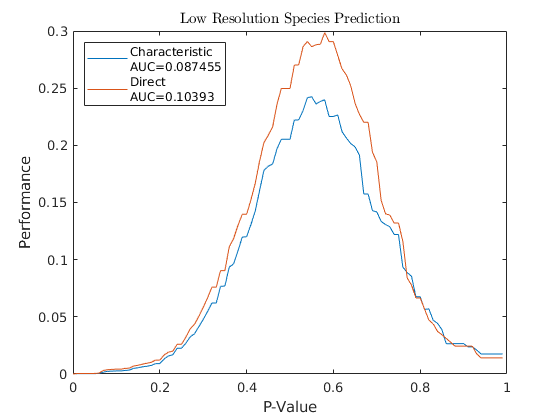

dlen = length('direct');

for i= 1:length(cfiles)
    cf = cfiles(i);
    suffix = cf{1}(clen+1:end)
    df = dfiles(dfiles == "direct" + suffix);
    PC = readmatrix("performance_data/" + cf)';
    PD = readmatrix("performance_data/" + df)';
    figure
    plotP(PC, PD, "")
    title(title_from_suffix(suffix))
    saveas(gcf, "plots/" + title_from_suffix(suffix) + ".png")
end

function plotP(PC, PD, name)
    plot(PC(:,1), PC(:,2));
    hold on 
    plot(PD(:,1), PD(:,2));
    hold off
    xlabel("P-Value");
    ylabel("Performance");
    aucC = trapz(PC(:,1), PC(:,2))
    aucD = trapz(PD(:,1), PD(:,2))
    
    title(name, "Interpreter","latex");
    legend(["Characteristic"+newline+"AUC="+aucC, "Direct"+newline+"AUC="+aucD], "Location","northwest")
end
function tit = title_from_suffix(suffix)
    tit = "";
    suffix = string(suffix);
    if contains(suffix, "_bolete.h5")
        tit = tit + "High Resolution";
    else
        tit = tit + "Low Resolution";
    end
    if contains(suffix, "_ed")
        tit = tit + " Edibility Prediction";
    else
        tit = tit + " Species Prediction";
    end
end